% clear all
% close all 
% clc

%% part 1.1
b = [0.505 1.01     0.505 ];
a = [1     0.7478   0.2722];

sys = tf(b(end:-1:1), a(end:-1:1))

sys =
 
  0.505 s^2 + 1.01 s + 0.505
  --------------------------
  0.2722 s^2 + 0.7478 s + 1
 
Continuous-time transfer function.



sys = tf(b, a, -1, 'Variable', 'z^-1')

sys =
 
  0.505 + 1.01 z^-1 + 0.505 z^-2
  ------------------------------
  1 + 0.7478 z^-1 + 0.2722 z^-2
 
Sample time: unspecified
Discrete-time transfer function.



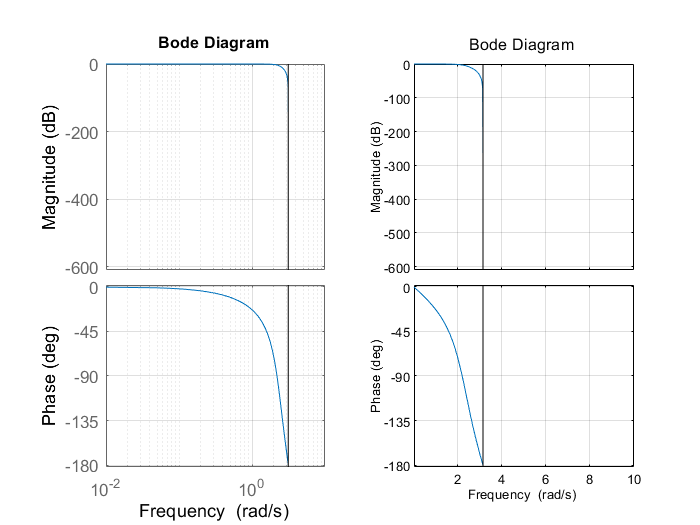

% figure;
% bode(sys);

opts = bodeoptions;
opts.FreqScale = 'linear';
figure
subplot(1,2,1)
bode(sys)
grid on
subplot(1,2,2)
bode(sys, opts)
grid on


% cut-off frequency is 3 rad/s, f = w/2/pi
clear opts sys ans

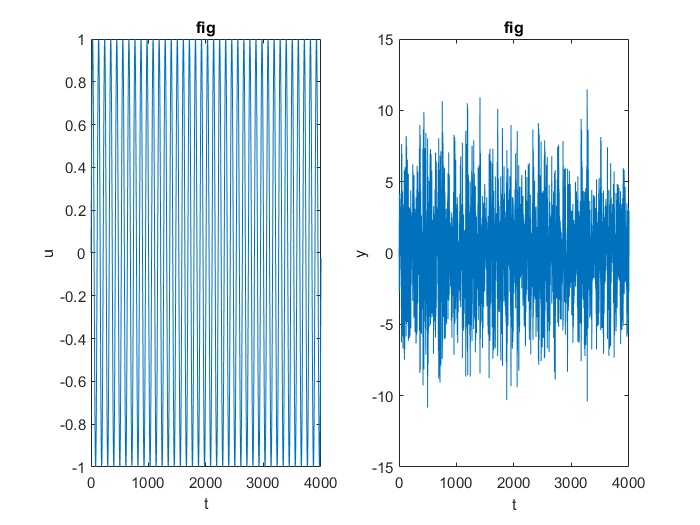

%% part 1.1
% from the true system
N = 2000;
f = 19;
offset = 0;
A = 1;
t = (0 : 1/N : 2)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1,2,1)
plot(u)
xlabel("t");
ylabel("u");
title("fig");

subplot(1,2,2)
plot(y)
xlabel("t");
ylabel("y");
title("fig");


% we now can know M is 3



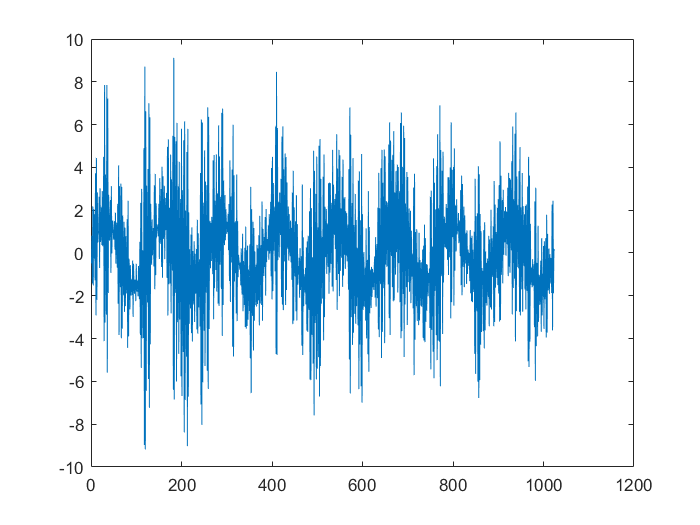

%% part2
% system setup
N = 1024;
Ts = 1;
n_freq = 128;

f = [0: 1: N-1]/128/Ts;
r = A * sin(2*pi*f) + offset;

[u,y] = assignment_sys_36(r);

%

figure;
plot(y)

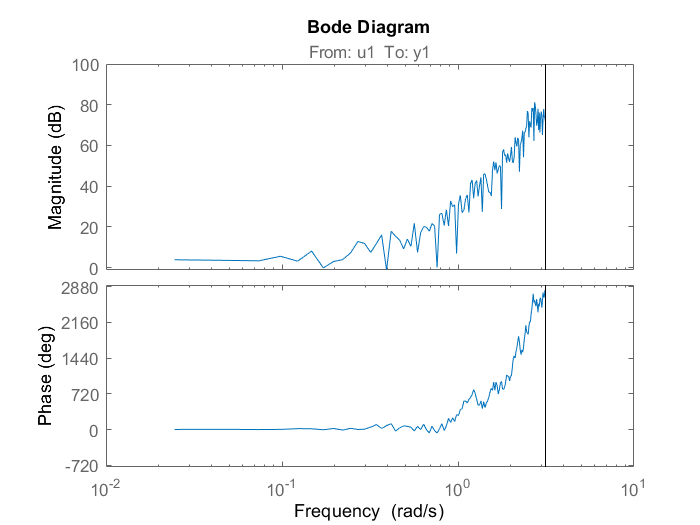


z = iddata(y, u);
G2 = etfe(z);
figure;
bode(G2);

%% part 3

N = 3000;





